clc
clear

[Dual] = dual_info(r,ReLoc,d2,d1,dual_para)
% 考虑1/6的三角形

ver_label =  [1, r*(r+1)/2+1, (r+1)*(r+2)/2]; % 三个顶点的序号

% 三角形三个顶点:  对于任意r不变
Dual.N(1,:) = (ReLoc.ac(:,ver_label(d1+1),d2))'; 
Dual.N(2,:) = [1/2,1/2,1/2]*r; Dual.N(2,d2) = 0; 
Dual.N(3,:) = [1/3,1/3,1/3]*r; 

%%%% 
if r ==1
    Dual.L = [2 3];
    
    Dual.S = [1 2 3];
    
    tN = ReLoc.ver(d2,ver_label(d1+1)); % 小三角形中有哪些计算节点（序号）
    
    
    Dual.Ld = cell(1,size(Dual.L,1));
    Dual.Ld{1,1} = [tN(1);
                     (-1)^(d1+1)];
                 
                 
    Dual.Sd = cell(1,size(Dual.S,1));
    Dual.Sd{1,1} = [tN(1);
                     1];
end

if r == 2
    Dual.N(4,:) = 2*dual_para.a*Dual.N(2,:) + (1-2*dual_para.a)*Dual.N(1,:);
    Dual.N(5,:) = 3/2*dual_para.b*Dual.N(3,:) + (1-3/2*dual_para.b)*Dual.N(1,:);
    
    
    Dual.L = [4 5; 5 3];
    
    Dual.S = [1 4 5; 1 2 3];
    
    
    tN = [ReLoc.ver(d2,ver_label(d1+1)),ReLoc.ver(d2,ver_label(2)+1)]; % 小三角形中有哪些计算节点（序号）
    
    Dual.Ld = cell(1,size(Dual.L,1));
    Dual.Ld{1,1} = [tN(1) tN(2);
                   (-1)^(d1+1) -(-1)^(d1+1)];
    Dual.Ld{1,2} = [tN(2);
                   -(-1)^(d1+1)];
                 
    Dual.Sd = cell(1,size(Dual.S,1));
    Dual.Sd{1,1} = [tN(1) tN(2);
                     1    -1];
    Dual.Sd{1,2} = [tN(2);
                     1   ];
end

if r == 3
    Dual.N(4,:) = dual_para.a*Dual.N(2,:) + (1-dual_para.a)*Dual.N(1,:);
    Dual.N(5,:) = dual_para.b*Dual.N(3,:) + (1-dual_para.b)*Dual.N(1,:);
    Dual.N(6,:) = dual_para.c*Dual.N(3,:) + (1-dual_para.c)*Dual.N(2,:);
    
    Dual.L = [4 5; 5 6; 6 2];
    
    Dual.S = [1 4 5; 3 5 6; 1 2 3];
    
    
    tN = [ReLoc.ver(d2,ver_label(d1+1)),ReLoc.ver(d2,ver_label(d1+1)+(-1)^(d1+1)), 5]; % 小三角形中有哪些计算节点（序号）
    
    Dual.Ld = cell(1,size(Dual.L,1));
    Dual.Ld{1,1} = [tN(1) tN(2);
                   (-1)^(d1+1) -(-1)^(d1+1)];
    Dual.Ld{1,2} = [tN(3)    tN(2);
                   (-1)^(d1+1) -(-1)^(d1+1)];
    Dual.Ld{1,3} = [tN(2);
                   -(-1)^(d1+1)];
                 
    Dual.Sd = cell(1,size(Dual.S,1));
    Dual.Sd{1,1} = [tN(1) tN(2);
                     1    -1];
    Dual.Sd{1,2} = [tN(3) tN(2);
                     1    -1];
    Dual.Sd{1,3} = [tN(2);
                     1   ];
end

Dual.N = Dual.N/r;

end



## 对于函数dua_linfo的说明：

r=1：  三角形一次元

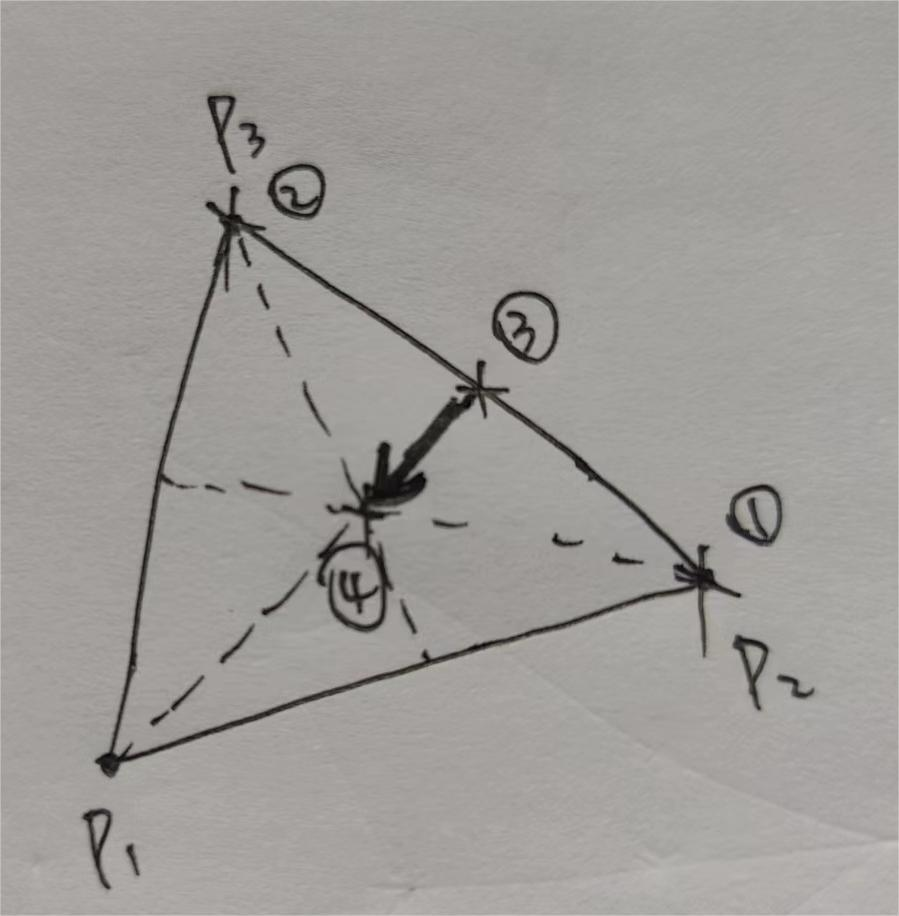

if r == 1
    Dual.N = zeros(4,size(ac,1)); % 初始化对偶节点
    Dual.N(1,:) = (ac(:,ReLoc(2)))';
    Dual.N(2,:) = (ac(:,ReLoc(3)))';
    Dual.N(3,:) = ((ac(:,ReLoc(2)) + ac(:,ReLoc(3)))/2)';
    Dual.N(4,:) = ((ac(:,ReLoc(1)) + ac(:,ReLoc(2)) + ac(:,ReLoc(3)))/3)';

Dual.N： 对偶节点，标记为圆圈i.

    Dual.L = zeros(1,2); % 初始化对偶有向线段
    Dual.L = [3 4]; % 对偶直线 

Dual.L： 对偶有向直线，对偶节点A指向对偶节点B.  (例如③指向④）

Dual.S = zeros(2,3); %初始化对偶三角形面，逆时针标号
    Dual.S = [1 3 4; 2 4 3];

Dual.S： 对偶三角形，三个顶点为对偶节点

    Dual.Ld = cell(1,size(Dual.L,1)); % 初始化对偶有向线段分配哪些计算节点，以及积分的正负取值
    Dual.Ld{1,1} = [ReLoc(2) ReLoc(3);
                      1        -1   ];  

Dual.Ld： 每条对偶有向直线的分配。例如：分配给计算节点P2为正，分配给计算节点P3为负

    Dual.Sd = cell(1,size(Dual.S,1)); % 初始化对偶三角形面分配哪些计算节点，以及积分的正负取值
    Dual.Sd{1,1} = [ReLoc(2);
                      1    ];  
    Dual.Sd{1,2} = [ReLoc(3);
                      1    ];    

Dual.Sd： 每条对偶三角形的分配。例如：第一个三角形分配给计算节点P2为正，第二个三角形分配给计算节点P2为正

end

r=2：  三角形二次元

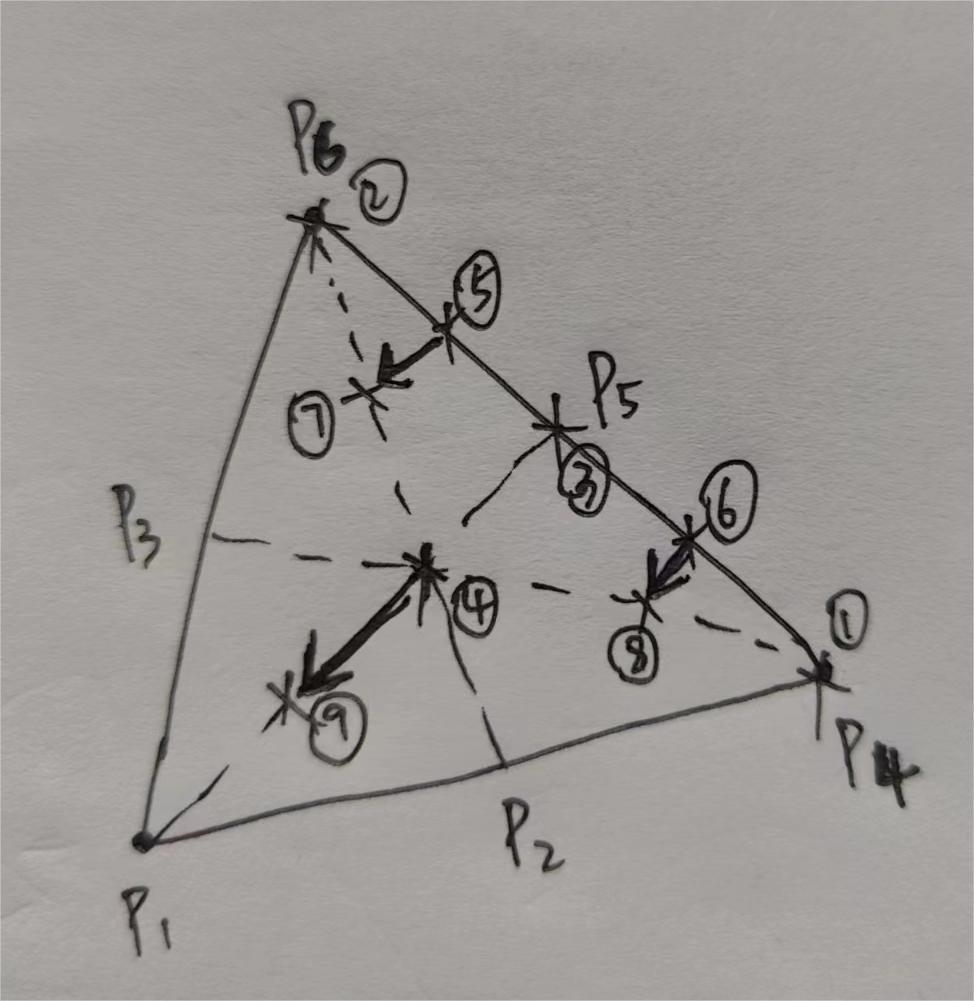

if r ==2
    Dual.N = zeros(9,size(ac,1)); % 初始化对偶节点
    Dual.N(1,:) = (ac(:,ReLoc(ver_label(2))))';
    Dual.N(2,:) = (ac(:,ReLoc(ver_label(3))))';
    Dual.N(3,:) = ((ac(:,ReLoc(ver_label(2))) + ac(:,ReLoc(ver_label(3))))/2)';
    Dual.N(4,:) = ((ac(:,ReLoc(ver_label(1))) + ac(:,ReLoc(ver_label(2))) + ac(:,ReLoc(ver_label(3))))/3)';
    
    Dual.N(5,:) = dual_para.a*Dual.N(1,:)+(1-dual_para.a)*Dual.N(2,:);
    Dual.N(6,:) = dual_para.a*Dual.N(2,:)+(1-dual_para.a)*Dual.N(1,:);
    Dual.N(7,:) = 3/2*dual_para.b*Dual.N(4,:)+(1-3/2*dual_para.b)*Dual.N(2,:);
    Dual.N(8,:) = 3/2*dual_para.b*Dual.N(4,:)+(1-3/2*dual_para.b)*Dual.N(1,:);
    Dual.N(9,:) = 3/2*dual_para.b*Dual.N(4,:)+(1-3/2*dual_para.b)*(ac(:,ReLoc(ver_label(1))))';
    
    Dual.L = zeros(3,2); % 初始化对偶有向线段
    Dual.L = [6 8; 5 7; 4 9]; % 对偶直线
    
    
    Dual.S = zeros(4,3); %初始化对偶三角形面，逆时针标号
    Dual.S = [1 3 4; 2 4 3;
              1 6 8; 2 7 5];
    
    
    Dual.Ld = cell(1,size(Dual.L,1)); % 初始化对偶有向线段分配哪些计算节点，以及积分的正负取值
    Dual.Ld{1,1} = [ReLoc(ver_label(2)) ReLoc(ver_label(2)+1);
                      1                        -1   ];  
    Dual.Ld{1,2} = [ReLoc(ver_label(3)-1) ReLoc(ver_label(3));
                      1                        -1   ];  
    Dual.Ld{1,3} = [ReLoc(ver_label(1)+1) ReLoc(ver_label(1)+2);
                      1                        -1   ];  
                  
    Dual.Sd = cell(1,size(Dual.S,1)); % 初始化对偶三角形面分配哪些计算节点，以及积分的正负取值
    Dual.Sd{1,1} = [ReLoc(ver_label(2)+1);
                      1    ];  
    Dual.Sd{1,2} = [ReLoc(ver_label(2)+1);
                      1    ];  
    Dual.Sd{1,3} = [ReLoc(ver_label(2))  ReLoc(ver_label(2)+1);
                      1                        -1 ];  
    Dual.Sd{1,4} = [ReLoc(ver_label(3))  ReLoc(ver_label(3)-1);
                      1                        -1];  
end

